### Problem 2.

Solve the following problems by programming the steepest descent method and the conjugate gradient method.

- Rosenbrok's function (the minimum is in a parabolic valley): $f=100{\left(x_2 -x_1^2 \right)}^2 +{\left(1-x_1 \right)}^2$, where ${\mathit{\mathbf{x}}}_0 ={\left\lbrack \begin{array}{cc}
-1\ldotp 2 & 1
\end{array}\right\rbrack }^{\mathrm{T}}$

- Wood's function (this problem has several local minima): $f=100{\left(x_2 -x_1^2 \right)}^2 +5{\left(1-x_1 \right)}^2 +90{\left(x_4 -x_3^2 \right)}^2 +{\left(1-x_3 \right)}^2 +10\ldotp 1\left\lbrace {\left(x_2 -1\right)}^2 +{\left(x_4 -1\right)}^2 \right\rbrace +19\ldotp 8\left(x_2 -1\right)\left(x_4 -1\right)$, where $x_0 ={\left\lbrack \begin{array}{cccc}
-3 & -1 & -3 & -1
\end{array}\right\rbrack }^{\mathrm{T}}$

close all; clear all; clc; 

**Rosenbrok's function**

fcnRosenbrok = @(x) (100*(x(2) - x(1)^2)^2 + (1 - x(1))^2);

**Wood's function**

fcnWood = @(x) 100*(x(2) - x(1)^2)^2 + 5*(1 - x(1))^2 + 90*(x(4) - x(3)^2)^2 + (1 - x(3))^2 + 10.1*((x(2) - 1)^2 + (x(4) - 1)^2) + 19.8*(x(2) - 1)*(x(4) - 1);
x0Wood = [-3, -1, -3, -1]';

#### (a)

Plot the iteration history of your function and find the optimal points.

gradRosenbrok = @(x) [-400*(x(2) - x(1)^2)*x(1) - 2*(1 - x(1));...
                      200*(x(2) - x(1)^2)];
x0Rosenbrok = [-1.2, 1]';
k = 0.05;
x1Rosenbrok = x0Rosenbrok - k*gradRosenbrok(x0Rosenbrok);
% hstryRosenbrok = conjugateGradientMethod(x1Rosenbrok, x0Rosenbrok, gradRosenbrok,  )

fcnRosenbrok $=100{\mathit{\mathbf{x}}}_a^{\mathrm{T}} {\mathit{\mathbf{A}}}_a {\mathit{\mathbf{x}}}_a +{\mathit{\mathbf{x}}}_b^{\mathrm{T}} {\mathit{\mathbf{A}}}_b {\mathit{\mathbf{x}}}_b$, where ${\mathit{\mathbf{x}}}_a ={\left\lbrack \begin{array}{cc}
x_1^2  & x_2 
\end{array}\right\rbrack }^{\mathrm{T}}$, ${\mathit{\mathbf{x}}}_b ={\left\lbrack \begin{array}{cc}
x_1  & 1
\end{array}\right\rbrack }^{\mathrm{T}}$, ${\mathit{\mathbf{A}}}_a =\left\lbrack \begin{array}{cc}
1 & -1\\
-1 & 1
\end{array}\right\rbrack$, ${\mathit{\mathbf{A}}}_b =\left\lbrack \begin{array}{cc}
1 & -1\\
-1 & 1
\end{array}\right\rbrack$. 

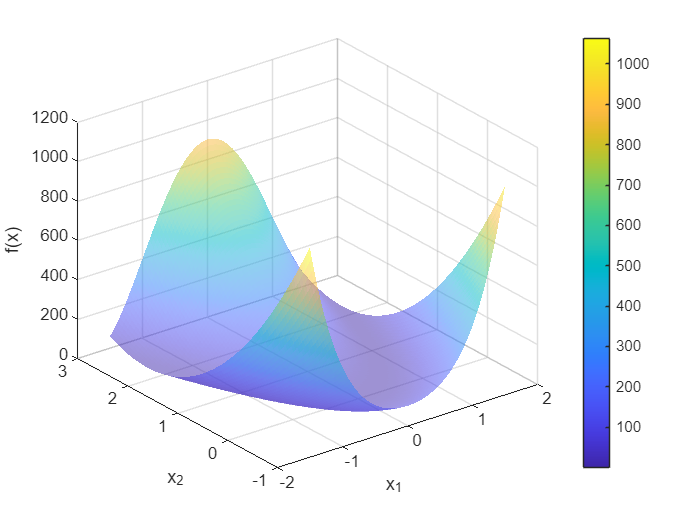

x1_range = linspace(-1.5, 1.5, 100);
x2_range = linspace(-1, 3, 100);
[X1, X2] = meshgrid(x1_range, x2_range);

Z = arrayfun(@(x1, x2) fcnRosenbrok([x1; x2]), X1, X2);

figRosenbrok = figure(1);
surf(X1, X2, Z, 'EdgeColor', 'none', 'FaceAlpha', 0.5);
xlabel('x_1');
ylabel('x_2');
zlabel('f(x)');
colorbar;


gradWood = @(x) [200*(x(2) - x(1)^2)*(-2*x(1)) - 10*(1 - x(1));...
                 200*(x(2) - x(1)^2) + 20.2*(x(2) - 1) + 19.8*(x(4) - 1);...
                 180*(x(4) - x(3)^2)*(-2*x(3)) - 2*(1 - x(3));...
                 180*(x(4) - x(3)^2) + 20.2*(x(4) - 1) + 19.8*(x(2) - 1)];